Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

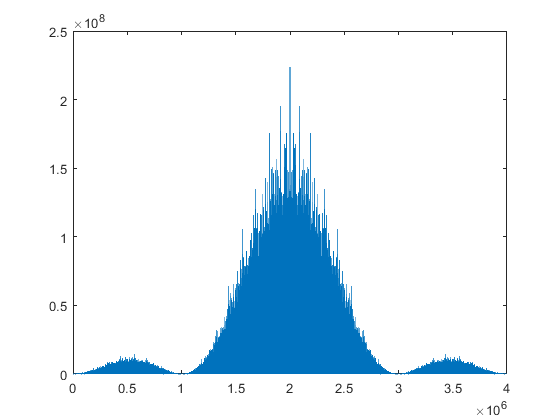

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);
%Tc=1/R_s/SpS;
d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 0.5;

% NRZ
for a=0:Nbits-1
    for b=1:SpS
        v_t(a*SpS+b) = in(a+1);
    end
end

figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t)).^2))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);

for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il primo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.2827
    0.5038
    0.4507
    0.5454


i = 1

BERs =     0.2682
    0.5054
    0.4438
    0.5510


i = 1

BERs =     0.2553
    0.5045
    0.4376
    0.5568


i = 1

BERs =     0.2443
    0.5042
    0.4323
    0.5621


i = 1

BERs =     0.2349
    0.5065
    0.4250
    0.5692


i = 1

BERs =     0.2274
    0.5068
    0.4175
    0.5758


i = 1

BERs =     0.2208
    0.5075
    0.4092
    0.5827


i = 1

BERs =     0.2147
    0.5083
    0.4017
    0.5900


i = 1

BERs =     0.2107
    0.5087
    0.3939
    0.5976


i = 1

BERs =     0.2059
    0.5100
    0.3858
    0.6058


i = 1

BERs =     0.2023
    0.5106
    0.3792
    0.6114


i = 1

Plotting

err_arr

err_arr =     0.2827
    0.2682
    0.2553
    0.2443
    0.2349
    0.2274
    0.2208
    0.2147
    0.2107
    0.2059


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

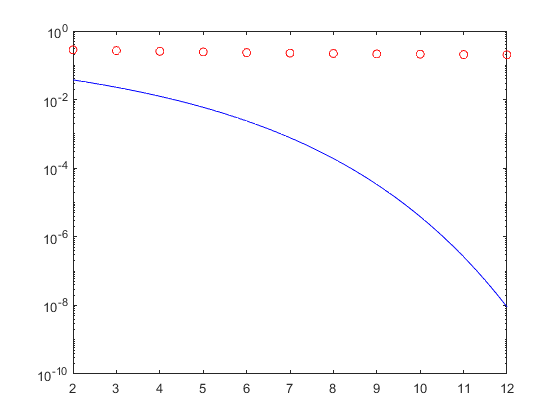

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

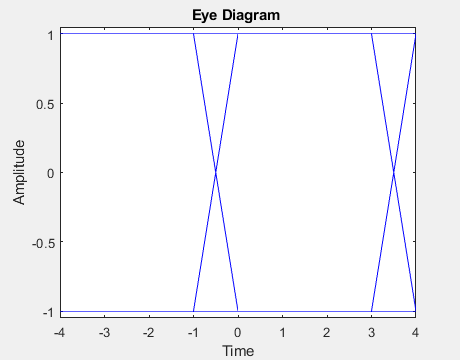

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

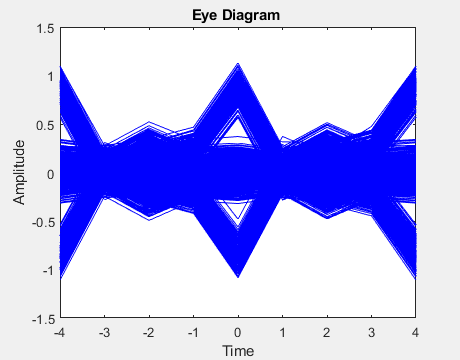



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = real(ifft(Y_f_nn));
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);